## Boas Práticas

clear all;
close all
clc;

## Leitura do arquivo .wav - audioread


[Y, FS] = audioread('Audio03.wav')

Y =          0         0
         0         0
    0.0000    0.0001
   -0.0001         0
         0   -0.0001
    0.0002    0.0001
   -0.0001    0.0000
   -0.0001   -0.0001
    0.0000   -0.0001
   -0.0000   -0.0001


FS = 8000

% Y é a amplitude, e FS é a frequencia do sinal lido

% TS = tempo entre dois pontos
TS = 1/FS

TS = 1.2500e-04

% Npontos = quantidade de pontos gravados
Npontos = length(Y);
% Vfinal é o tempo do audio
Vfinal = (Npontos-1)*TS

Vfinal = 2.9365

% Vetor tempo usado para plots
tempo = linspace(0,Vfinal,Npontos)

tempo =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0028    0.0029    0.0030    0.0031    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


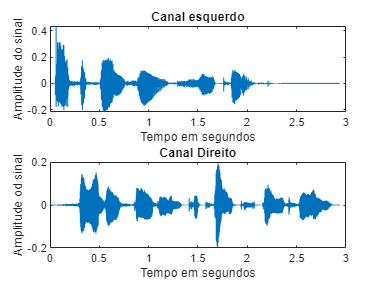


figure(1);

subplot(2,1,1)
plot(tempo, Y(:,1))
xlabel("Tempo em segundos")
ylabel("Amplitude do sinal")
title("Canal esquerdo")
subplot(2,1,2)
plot(tempo, Y(:,2))
xlabel("Tempo em segundos")
ylabel("Amplitude od sinal")
title("Canal Direito")

## Ouvir um arquivo .wav

%sound(Y,FS);

## FFT


FY = fftshift(fft(Y));

## Visualizar o FFT

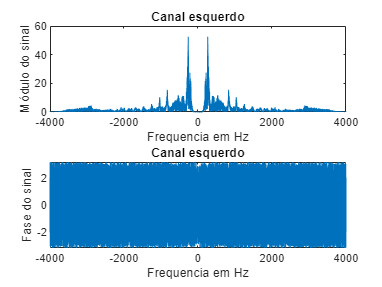

frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2)

subplot(2,1,1)
plot(frequencia,abs(FY(:,1)))
xlabel("Frequencia em Hz")
ylabel("Módulo do sinal")
title("Canal esquerdo")

subplot(2,1,2)
plot(frequencia,angle(FY(:,1)))
xlabel("Frequencia em Hz")
ylabel("Fase do sinal")
title("Canal esquerdo")


% subplot(2,1,1)
% xlim([-3000, 3000])
% ylim([24 7400])